# Race Path Optimization

% Please make sure that root/src is on the MATLAB path
% (if not: run root/src/init)
clear
clc
init()

Appending MATLAB search path...
Path Optimization root found, relevant paths added.


## 1) Path Representation

The first step of the best lap time of a racing path is finding a proper discretization of it, which is needed to compute some of its geometrical properties (arc length, curvature, etc.). Since these paths will be automatically generated, it is necessary to apply some constraints that make sure it does not exceed the boundaries of the track. Thus, a bounded linear combination of the track boundaries is a convenient method to describe it with.

A point $\mathbf{P}_i$ on the path can be written as: 


$$\mathbf{P}_i = \mathbf{A}_i + \alpha_i (\mathbf{B}_i-\mathbf{A}_i)$$
       
$$\forall \alpha_i \in [0,1]$$


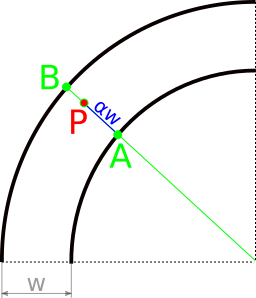

*Note: this definition imposes some requirements on the track representation:*

- *both boundaries need to have the same number of points*

- *for each point on one of the boundaries, there has to be a matching point on the other one, approximately on the same normal of the center line*

- *as an added requirement of the implementation: the points on both boundaries have to be ordered in the desired direction*

Once the path points are given, a method if interpolation has to be defined. The simplest way is to connect these points with straight lines but in order to get a contiunous curvature, a $C^2$ continuous interpolation function is required at least. This can be achieved with cubic interpolating splines, for which we used the built-in *spline* function (separately for the interpolation of each component).

As an arbitrary choice, the parameter range of every spline $r$ is set to $\xi \in[0,1]$, and the difference between each point's spline parameter is proportional to their euclidean distance.


$$\mathbf{r}=
\pmatrix{
r_x(\xi) \cr
r_y(\xi)
}$$
              
$$\xi \in [0,1]$$
        
$$|\xi_i-\xi_j| = \gamma||\mathbf{P}_i - \mathbf{P}_j||_2$$


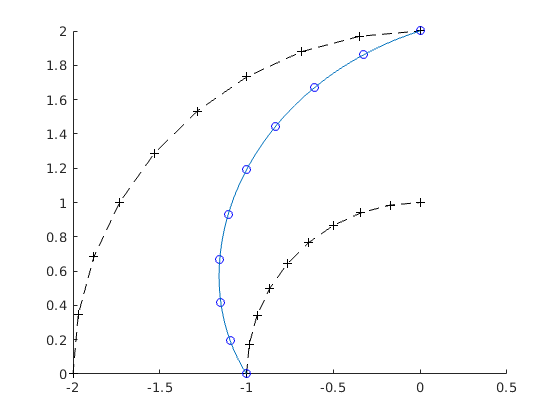

% PATH DEFINITION
% Define two circular boundaries
t           = linspace(pi,pi/2,10)';
innerBound  = 1 * [cos(t), sin(t)];
outerBound  = 2 * [cos(t), sin(t)];

% Define the coefficients of the linear combination
% --> go from the inner boundary to the outer one
alpha       = linspace(0,1,length(t));

% Get points on the path
pathPoints  = generatePathPoints(innerBound,outerBound,alpha);

% Generate interpolating splines through the path points
[splineX, splineY]  = cubicSpline2D(pathPoints);

% Plot everything on the same axes
figure;
hold on;
plot(innerBound(:,1),innerBound(:,2),'k--+');
plot(outerBound(:,1),outerBound(:,2),'k--+');
plot(pathPoints(:,1),pathPoints(:,2),'bo');
plotSpline(splineX,splineY);
hold off;

*Note: while the defined path points definitely stay within the track boundaries, there is no guarantee that the interpolated points in between them do so as well. The assumption here is that a typical good racing path does not have large oscillations (that would result in the interpolated points being well outside the boundaries), and that the track points are dense enough to render the occasional boundary violations neglectable. The drawback of this representation is now clear: the number of parameters are coupled with the accuracy of the track description.*

## 2) Computing Geometric Properties

The main reason why splines are used to interpolate the path points is the need to compute arc length and curvature values that are continuous. With the continuity conditions satisfied, we can use differential geometry to find the curvature $\kappa$ at a point, and the arc length $s$ between two points on the spline:


$$\kappa=
\frac{
||\mathbf{r}' \times \mathbf{r}''||_2
}{
|| \mathbf{r}' ||_2^3
}$$
                       
$$\mathbf{r}':=\frac{d\mathbf{r}}{d\xi}$$



$$s_{ij}=\int_{\xi_i} ^{\xi_j}
|| \mathbf{r}' ||_2 d\xi$$


% GEOMETRIC PROPERTIES
% Define a unit circle
t           = linspace(0,2*pi,100)';
circle      = [cos(t),sin(t)];

% Generate the spline
[splx,sply] = cubicSpline2D(circle);

% Compute its curvature at some points
tSamples    = [0.25,0.5,0.75]';
kappa       = curvature(splx,sply,tSamples)

kappa =     1.0000
    0.9998
    1.0000



% Compute the arc lengths between the sample points
s           = arcLength(splx,sply,tSamples)

s =          0
    1.5708
    3.1416



% Compute the circumference (arc length from start to end)
l           = diff(arcLength(splx,sply,[0;1]))

l = 6.2832

*Note: the arcLength function performs an arbitrary sampling of the spline if the argument sample points are too coarse (if the interval between the provided sample points exceed the intervals between spline parameters of the interpolated points). See the arcLength function definition in inc/preprocessing/arcLength for specifics.*

## 3) Track Definition

To store, pass and operate on tracks more conveniently, we created a structure that holds all necessary data in four fields:

- bound1 :            nx2 array containing the points of one of the boundaries (typically the inner one)

- bound2 :            nx2 array containing the points of the other boundary (typically the outer one)

- center   :            nx2 array containing the points of the center line (can be generated uing the boundaries)

- staticPoints :     1xm array holding indices of section boundaries, see Sectionwise Optimization

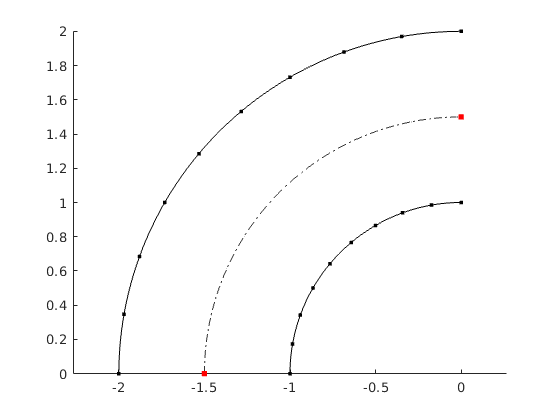

% TRACK STRUCTURES
% The inner and outer boundaries were defined in the previous code block
track.bound1        = innerBound;
track.bound2        = outerBound;
track.center        = 0.5 * (innerBound + outerBound);
track.staticPoints  = [1,length(innerBound)];

plotTrack(track);

To import a new track in the Path Optimization App, the track needs to be wrapped in a function that starts with *track_* and has the following signature:

*function track = track_trackName(nPointMultiplier)*

The *track *return value should be a valid track structure with all four fields mentioned above, and the *nPointMultiplier *argument should control the number of points the track consists of (*nPointMultiplier = 1.0* means the track should have the default number of points, *2.0* means it has double that, etc.).

The points along the track should be sufficiently distributed, see the section on Track Preconditioning for more information.

## 4) Track Preconditioning

Accurately defining the track boundaries is not enough; the distribution of the points have to respect some extra guidelines in order for the optimization to be successful. Having uniformly spaced points might restrict the path solution space, especially around corners. Ideally, straight sections of a track should have a coarse distribution of points, while regions with high curvature must be more densely packed. This, is of course, often not the case with automatically generated tracks and to solve this problem, the imported tracks need to be preconditioned.

Using the same method as with the path, the curvature and arc length values (measured from the starting point) can be computed for the track boundaries as well, allowing an arbitrary resampling of the interpolating spline using its geometry. The current implementation of the resampling calculates $\hat{\eta_i} = 

\int_0^{\xi_i}(\kappa+ \overline{\kappa} )d\xi
$ and creates and inverse mapping to the original parameter range $[0,1]$. This mapping process presents us with an extra degree of freedom that we can use later: the number of mapped points can be chosen arbitrarily and does not have to match the original number of points. This is very useful when an increased (or decreased) number of parameters is needed for the optimization, since the track does not have to be manually redefined in the process.

Applying this algorithm to both boundaries of the track would result in mismatched point-pairs (two points on the boundaries that have been on the same center normal before the transformation would lie on different normals afterwards) because the ratio of the curvatures on the inner and outer boundaries is not necessarily constant. To avoid this issue, the resampling is only performed on the center line and the corresponding points on the boundaries are set via a closest point finding algorithm.

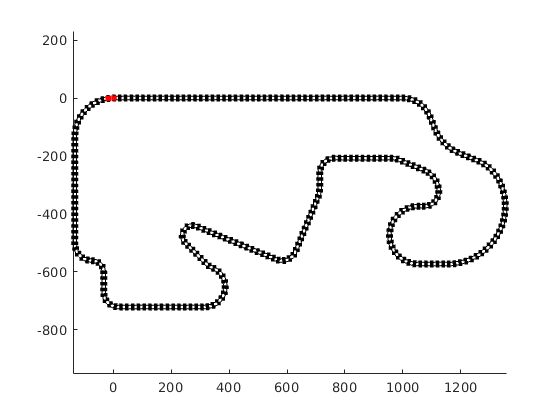

% TRACK PRECONDITIONING
clear track

% Import a set of equally spaced track data and create a track structure
trackData           = csvread('doc/docExamples/Catalunya.csv');
track.bound1        = trackData(:,1:2);
track.bound2        = trackData(:,3:4);
track.center        = trackData(:,5:6);
track.staticPoints  = [1,length(track.bound1)];

% Plot the equally spaced track
plotTrack(track,'bound1','bound2');

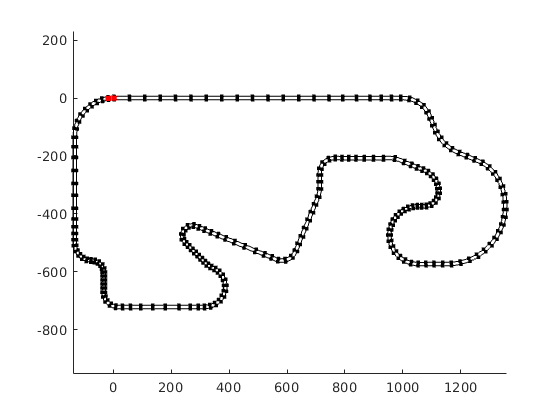


% Perform resampling and set the number of new points to 3/4 the
% original number of points
nPointMultiplier    =  0.75;
track               = redistributePointsOnTrack(track,nPointMultiplier);
plotTrack(track,'bound1','bound2');

## 5) Vehicle Models

In the context of path optimization, a vehicle model refers to a set of functions that define the limits of what that vehicle is capable of. Currently, these set of functions are the following:

- The maximum acceleration as a function of velocity              $a_{max}(v)$           $a_{max}>=0$   $ \forall v>0$

- The maximum deceleration as a function of velocity              $a_{min}(v)$           $a_{min}<=0$    $\forall v>0$

- The maximum cornering velocity as a function of curvature  $v_{max}(\kappa)$           $v_{max}>0$       $\forall \kappa>0$

Since these functions have no closed form or are too complex to exactly compute, lookup tables are used approximate them. Every such vehicle model should have its own folder in inc/dynamics/vehicles, and that folder should contain the following three *csv* files that store their corresponding set of data:

- *accelerationTable.csv*

- *decelerationTable.csv*

- *corneringVelocityTable.csv*

*Note: each csv file should have two columns with the same length; the first column storing the data sites, the second storing the corresponding values. Every quantity should be in SI base units or their derivatives (meters, seconds, m/s, radians, etc.). The data sites have to be unique and sorted in ascending order.*

For automatic table generation of Simulink vehicle models, see ${ANKIT'S DOCUMENTATION}.

The table lookups return the first value if the requested point is less than the first data site, and similarly returns the last value if the requested point is greater than the last data site. In between samples, linear interpolation is performed (this is the reason why data sites should be unique).

In the app by default, the lookup table defined in *inc/utilities/TableLookup* uses a linear search to find the bounding data sites, which is faster for relatively small tables and single lookups (single lookups are more common during the optimization). This can be changed to the MATLAB function *interp1* by specifying it in the constructor of *TableLookup*.

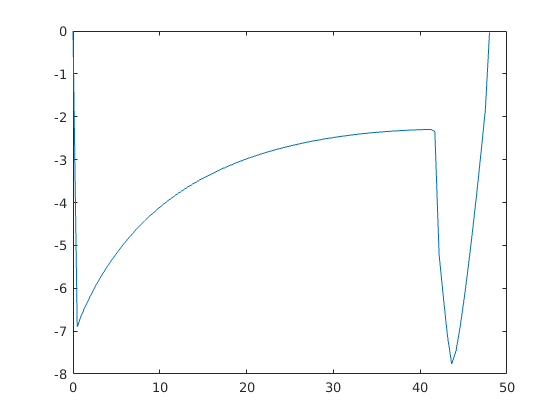

% VEHICLE MODELS AND LOOKUP TABLES
% Create a lookup table and specify the lookup method
lookup  = TableLookup('inc/dynamics/vehicles/SimulinkModel/corneringVelocityTable.csv','linearSearch');

% Plot interpolated values
xRange  = [lookup.data(1,1), lookup.data(end,1)];
sites   = linspace( xRange(1), xRange(2), 100 );
plot(sites,lookup.method(sites));


% Compare interp1 and linear search performance for single lookups
nLookups    = 1e4;
sites       = xRange(1) + (xRange(2)-xRange(1)) * rand(nLookups,1);

tic
for k=1:nLookups
    v = lookup.method(sites(k));
end
fprintf('Linear search finished lookup in %d[s]\n', toc)

Linear search finished lookup in 3.161850e-01[s]



interp1Lookup = TableLookup('inc/dynamics/vehicles/SimulinkModel/corneringVelocityTable.csv','interp1');
tic
for k=1:nLookups
    v = interp1Lookup.method(sites(k));
end
fprintf('Interp1 finished lookup in %d[s]\n', toc)

Interp1 finished lookup in 1.608997e+00[s]


## 6) The Evaluator Class

This section covers the evaluator class that has nothing to do with the theory of the optimization but only its implementation. It is derived from the handle class (meaning it behaves much like references in C++) and stores settings, function handles, and data that is requested to be written during the optimization. Most functions in the evaluation pipeline rely on some field of the evaluator to fulfil their tasks. 

Members that should be set when setting up an optimization:

- Evaluator.maxAccelerationFunction           : function handle of the acceleration table lookup (see Vehicle Model)

- Evaluator.maxDecelerationFunction           : function handle of the deceleration table lookup (see Vehicle Model)

- Evaluator.maxVelocityFunction                  : function handle of the cornering velocity lookup (see Vehicle Model)

- Evaluator.targetFunction                            : function handle of the objective function (see Objective Functions)

- Evaluator.startVelocity                                : initial velocity of the vehicle, 0 by default

- Evaluator.nSubdivisions                             : number of subsamples between interpolation points (see Objective Functions)

- Evaluator.ojectiveMultiplier                         : coefficient by which the objective is scaled after normalizing, 1 by default

Some member variables control whether some parts of the evaluation get executed or not. In order to perform postprocessing, these members have to be set to gain access to the desired results. 

Members that should be set before postprocessing:

- Evaluator.writeDetails                                 : controls whether data is written to the evaluator during path evaluation

- Evaluator.optimRange                                : index of the section to be optimized, 0 by default (full path) (see Sectionwise Optimization)

By default, data is not written to the evaluator since they would get overwritten during the next iteration. If *Evaluator.writeDetails* is true however, quantities that are computed during path evaluation are copied to their corresponing fields in the evaluator. Note that quantities that were not used will remain empty (for example: velocity data is not written during a curvature minimization). 

Members that store data generated during the evaluation of a path:

- Evaluator.splineParams                              : spline parameters at which the path was evaluated (see Path Representation)

- Evaluator.curvatures                                  : curvature values at the evaluated spline parameters (see Geometric Properties)

- Evaluator.time                                            : time values at the evaluated spline parameters

- Evaluator.velocities                                    : velocity magnitudes at the evaluated spline parameters

% THE EVALUATOR CLASS
% Construct an evaluator
evaluator                     = Evaluator();

% Set vehicle model
evaluator.maxAccelerationFunction   = TableLookup(  'inc/dynamics/vehicles/SimulinkModel/accelerationTable.csv').method;
evaluator.maxDecelerationFunction   = TableLookup(  'inc/dynamics/vehicles/SimulinkModel/decelerationTable.csv').method;
evaluator.maxVelocityFunction       = TableLookup(  'inc/dynamics/vehicles/SimulinkModel/corneringVelocityTable.csv').method;
                                                
% Set optimization settings
evaluator.targetFunction      = @objective_lapTime_rateLimitedBrakeCheck;
evaluator.nSubdivisions       = 10;
evaluator.objectiveMultiplier = 100;


% /... run optimization .../


% Set up evaluator for postprocessing
evaluator.optimRange          = 0;
evaluator.writeDetails        = true;


% /... evaluate path to gather data .../


% Access data from evaluator
xi          = evaluator.splineParams;
kappa       = evaluator.curvatures;
T           = evaluator.time;
v           = evaluator.velocities;

## 7) Objective Functions

Objective functions combine the vehicle model and the path to compute a scalar that is then used in the optimization algorithm as a target to be minimized. They are located in *root/inc/pathOptimization* and begin with *objective_. *Every objective function receives the spline representation of the path and an instance of the *Evaluator* class that contains function handles to the vehicle model, and provides storage for the relevant data generated during the calculation of the objective (see The Evaluator Class), so all objective functions must have the following signature:

*function objectiveValue = objective_objectiveName(splineX, splineY, evaluator)*

In most cases, the objective function has to perform some sampling on the spline; this process will be referred to as subsampling, since the interpolation points can be regarded as the primary sampling of the spline and subsampling further divides the intervals between interpolation points. The number of subsamples is defined by *Evaluator.nSubdivisions, *which has great influence on the accuracy and the processing time of the optimization.

See the objective example.

% Set up the evaluator
evaluator                       = Evaluator();
evaluator.maxVelocityFunction   = TableLookup('inc/dynamics/vehicles/SimulinkModel/corneringVelocityTable.csv').method;

% Define a path (circular arc of radius 100)
xi          = linspace(pi,pi/2,20)';
pathPoints  = 100 * [cos(xi), sin(xi)];
[splx,sply] = cubicSpline2D(pathPoints);

% Execute the example objective function
lapTime     = objective_exampleObjective(splx,sply,evaluator)

lapTime = Inf

Since the vehicle models only define the limits of what the specific vehicle is capable of, the objective function has to define the specifics of the dynamics. Some aspects of the vehicle model may be neglected, or some additional constraints applied in the objective function (example: neglecting the acceleration and deceleration limits and only including the maximum velocity limit results in an infinite acceleration model). The following objective functions are implemented:

- ***objective_length       ***                                                                                                                                                                                                                 this objective function returns the length of the input path, meaning that no information about the vehicle is used. Thus the resulting optimum path is going to be the shortest one.

- ***objective_curvature  ***                                                                                                                                                                                                                 returns the squared integral of the curvature along the entire path. The resulting optimum path is the one with minimum overall curvature.

- ***objective_lapTime_infiniteAcceleration      ***                                                                                                                                                                                                               returns the lap time assuming the vehicle always travels at its maximum allowable speed (that depends on the curvature).

- ***objective_lapTime_rateLimited ***                                                                                                                                                                                                                   returns the lap time assuming the vehicle always tries to maximize its velocity, but can only accelerate/brake according to the provided limits.

- ***objective_lapTime_rateLimitedBrakeCheck  ***                                                                                                                                                                                                                returns the lap time assuming that the vehicles maximizes its velocity but never exceeds the maximum allowable speed (starts braking just in time to stay within speed limits)

The last objective effectively uses and respects all provided data of the vehicle and is the most accurate of the implemented lap time calculators. However, keep in mind that between subsamples, the acceleration is assumed to be constant so a coarse subsampling might result in an inaccurate lap time estimatie.

## 8) Path Optimization

Since all implemented objective functions are nonlinear and all parameters are constrained to remain in the range $[0,1]$, a nonlinear constrained optimization algorithm is needed. The chosen function is [fmincon](https://www.mathworks.com/help/optim/ug/fmincon.html) from the optimization toolbox of MATLAB but can be swapped out to any other function with little modification to the code. Even though the problem can be converted to an unconstrained one (the optimization parameters could be passed through a sigmoid function for example), leaving it in its original constrained form and using constrained optimization has yielded more reliable results so far.

At its core the optimization minimizes the objective function, accessed through Evaluator.targetFunction but in order to make that possible, an interface is created between them: the *evaluatePath* function evaluates a path defined by the optimization parameters, with respect to the objective function by executing the following tasks:

- build a path based on the track and the parameters supplied by the optimization algorithm

- call *Evaluator.targetFunction* with the current path

- return the objective value with some scaling

The scaling factor of the objective value is set by the user in Evaluator.objectiveMultiplier and is necessary for cases with a high number of variables (>100). However, cases with much higher number of variables might perform better with sectionwise optimization instead.

The optimization itself is carried out by the *optimizePath *function, which accepts the following property-value pair arguments:

- ***'x0'  ***                                                                                                                                                                                                                                                                        The initial set of parameters to start the optimization from

- ***'track'   ***                                                                                                                                                                                                                                                          The track to optimize for

- ***'evaluator'***                                                                                                                                                                                                                                         Instance of the Evaluator class, carrying the vehicle model and the objective function

- ***'optimoptions'***                                                                                                                                                                                                                                                Optimization algorithm settings from the [optimoptions](https://www.mathworks.com/help/optim/ug/optim.problemdef.optimizationproblem.optimoptions.html) function, specified for *fmincon*

- ***'axesHandle'  ***                                                                                                                                                                                                                                          Handle of the GUI axes, only for internal use with the app

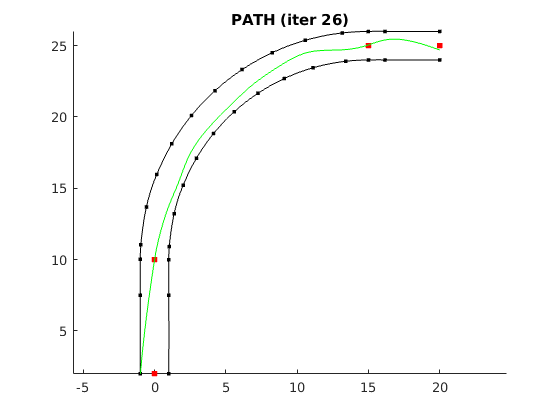

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    1.600000e+03    0.000e+00    1.792e+03
    1      36    1.569455e+03    0.000e+00    2.965e+03    4.200e-01
    2      59    1.567091e+03    0.000e+00    1.341e+04    1.347e-01
    3      93    1.566788e+03    0.000e+00    4.169e+04    1.709e-05
    4     111    1.566787e+03    0.000e+00    4.169e+04    3.420e-05
    5     131    1.566006e+03    0.000e+00    5.542e+04    1.436e-01
    6     150    1.564353e+03    0.000e+00    5.283e+04    1.923e-01
    7     168    1.562547e+03    0.000e+00    4.687e+04    2.762e-01
    8     186    1.560477e+03    0.000e+00    4.138e+04    3.767e-01
    9     205    1.560025e+03    0.000e+00    9.029e+04    1.792e-01
   10     228    1.559461e+03    0.000e+00    7.614e+03    4.335e-04
   11     246    1.559452e+03    0.000e+00    7.614e+03    3.415e-04
   12     265    1.557761e+03    0.000e+00    7

   23     500    1.552768e+03    0.000e+00    4.004e+04    3.290e-08
   24     525    1.552768e+03    0.000e+00    1.907e+04    4.249e-09
   25     543    1.552768e+03    0.000e+00    2.004e+04    3.547e-09

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<

% PATH OPTIMIZATION
% Optimize an L-bend with nonzero entering velocity

% Load track
track                       = track_LBend(0.7);

% Define the center line as the starting point of the optimization
x0                          = 0.5 * ones( length(track.bound1), 1 );

% Set up the evaluator
evaluator                           = Evaluator();
evaluator.targetFunction            = @objective_lapTime_rateLimitedBrakeCheck;
evaluator.maxAccelerationFunction   = TableLookup(  'inc/dynamics/vehicles/SimulinkModel/accelerationTable.csv').method;
evaluator.maxDecelerationFunction   = TableLookup(  'inc/dynamics/vehicles/SimulinkModel/decelerationTable.csv').method;
evaluator.maxVelocityFunction       = TableLookup(  'inc/dynamics/vehicles/SimulinkModel/corneringVelocityTable.csv').method;
evaluator.nSubdivisions             = 11;
evaluator.objectiveMultiplier       = 100;
evaluator.startVelocity             = 10;

% Set and generate options for fmincon
options                     = optimoptions( 'fmincon',                  ... 
                                            'OutputFcn',@ProgressPlot,  ...
                                            'Display','iter',           ...
                                            'StepTolerance',1e-9,       ...
                                            'MaxIterations',400,        ...
                                            'UseParallel',true  );
                                        
% Run the optimization
alpha                       = optimizePath( 'track',track,              ...
                                            'x0',x0,                    ...
                                            'evaluator',evaluator,      ...
                                            'optimoptions',options);


% Configure evaluator for postprocessing
evaluator.optimRange        = 0;
evaluator.writeDetails      = true;
                                            
% Plot the optimized path
plotSolution(track,alpha,evaluator);

## 9) Sectionwise Path Optimization

When considering large tracks, one has to find a delicate balance between the accuracy of the optimization and the number of variables. While reducing the number of parameters and increasing the number of subsamples results in an approximately identical lap time accuracy, the space of representable paths shrink, most probably resulting in a suboptimal trajectory. Several approaches exist that effectively reduce the number of variables in a problem, but the currently implemented one is subproblem optimization (referred to as sectionwise optimization from this point on). The basic idea is to optimize the path for the entire track for a coarse distribution of parameters first, and using the result of that as a starting point, sequentially optimize separate sections of the track with an increased number of variables per section. The objective is still calculated for the entire track.

*Note: this approach has several downsides that have not been balanced yet, hence it is still a work in progress. First of all, the path obtained from the coarse optimization has to be adequately close to the real optimal path, and the section boundaries have to be properly placed. If these conditions are not met, otherwise sectionwise optimizations might converge to different local optima.*

Section boundaries are defined in the *staticPoints* field of the track structure, which mark the indices of the points on the track that separate neighbouring sections (red dots on plotted tracks).

The reduction of the number of parameters is not only necessary to save computation time, but also because convergence might not be achieved for problems with too many optimization variables (in which case the optimized path tends to remain on the center line).

The way sectionwise optimization is currently implemented is as follows:

- Find the optimal path for a coarse track

- Enrich the number of variables in the first section

- Run an optimization with only the variables from the first section, starting from the result of the global optimization

- Increase the number of variables for the next section

- Run an optimization for the next section of variables, using the previous optimization result as a starting point

- Repeat steps 4-5 until the end of the track is reached

In this case two instances of the Evaluator class are needed (both must have the same objective function and vehicle model, but can have different subsampling), one for the global and one for the sectionwise (local) optimization.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    1.600000e+01    0.000e+00    3.690e+01
    1      44    1.572563e+01    0.000e+00    3.077e+01    9.978e-03
    2      62    1.567956e+01    0.000e+00    7.136e+01    1.996e-02
    3      84    1.555765e+01    0.000e+00    4.238e+01    1.995e-02
    4     103    1.545299e+01    0.000e+00    3.862e+01    9.976e-03
    5     124    1.489343e+01    0.000e+00    8.995e+00    1.995e-02
    6     142    1.462811e+01    0.000e+00    1.893e+01    3.989e-02
    7     165    1.451357e+01    0.000e+00    1.054e+01    1.993e-02
    8     184    1.442887e+01    0.000e+00    1.124e+01    1.987e-02
    9     204    1.424995e+01    0.000e+00    1.840e+01    1.051e-01
   10     228    1.411910e+01    0.000e+00    1.921e+01    2.624e-02
   11     246    1.397784e+01    0.000e+00    1.542e+01    2.542e-02
   12     264    1.369141e+01    0.000e+00    2

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.800000e+01    0.000e+00    2.074e+02
    1      19    7.392753e+00    0.000e+00    9.073e+01    7.467e-02
    2      26    6.044618e+00    0.000e+00    1.136e+02    1.484e-01
    3      33    3.830600e+00    0.000e+00    4.416e+01    3.520e-01
    4      48    3.722628e+00    0.000e+00    4.941e+01    1.947e-02
    5      55    3.326373e+00    0.000e+00    4.341e+01    1.928e-02
    6      62    1.451957e+00    0.000e+00    1.095e+01    3.693e-01
    7      68    1.260641e+00    0.000e+00    9.584e+00    1.109e-01
    8      75    1.234769e+00    0.000e+00    1.050e+01    8.777e-02
    9      81    1.158287e+00    0.000e+00    7.961e+00    1.710e-01
   10      87    1.171915e+00    0.000e+00    1.959e-01    6.894e-02
   11      93    1.171348e+00    0.000e+00    1.000e-01    1.690e-03
   12      99    1.133212e+00    0.000e+00    2

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      19    2.400000e+01    0.000e+00    2.749e+02
    1      45    2.179067e+01    0.000e+00    2.745e+02    7.195e-02
    2      66    2.102425e+01    0.000e+00    2.393e+02    3.595e-02
    3      89    2.059305e+01    0.000e+00    2.665e+02    7.103e-02
    4     110    2.035879e+01    0.000e+00    2.583e+02    3.592e-02
    5     133    2.022120e+01    0.000e+00    3.150e+02    7.176e-02
    6     156    9.520773e+00    0.000e+00    3.654e+01    7.189e-02
    7     181    8.328929e+00    0.000e+00    3.375e+01    3.589e-02
    8     206    7.826229e+00    0.000e+00    1.842e+01    1.795e-02
    9     227    7.777598e+00    0.000e+00    3.301e+01    1.788e-02
   10     250    7.441821e+00    0.000e+00    2.375e+01    3.586e-02
   11     272    7.331638e+00    0.000e+00    2.677e+01    1.789e-02
   12     296    6.904286e+00    0.000e+00    1

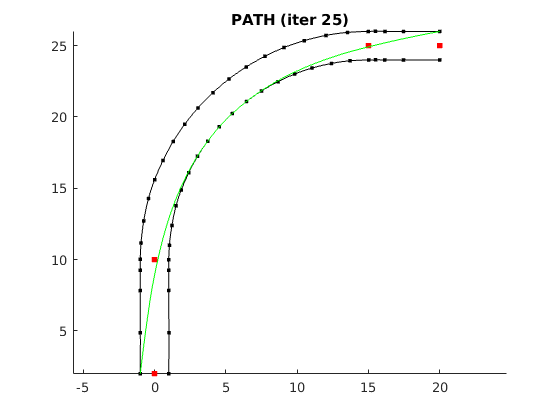

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.600000e+01    0.000e+00    5.365e+02
    1      21    1.697854e+01    0.000e+00    2.995e+02    2.070e-02
    2      28    9.208244e+00    0.000e+00    1.834e+02    4.137e-02
    3      36    6.680465e+00    0.000e+00    2.098e+02    1.566e-01
    4      42    4.155759e+00    0.000e+00    7.823e+01    6.211e-01
    5      49    4.145094e+00    0.000e+00    2.916e+02    4.686e-02
    6      55    3.544412e+00    0.000e+00    2.330e+01    8.576e-02
    7      62    3.453935e+00    0.000e+00    9.391e+00    6.469e-02
    8      69    3.477404e+00    0.000e+00    3.535e+00    2.227e-02
    9      75    3.477295e+00    0.000e+00    1.972e-01    5.428e-04
   10      81    3.477258e+00    0.000e+00    1.000e-01    1.008e-04
   11      87    3.417716e+00    0.000e+00    7.957e-01    5.470e-02
   12      93    3.409541e+00    0.000e+00    2

% SECTIONWISE OPTIMIZATION
% Set up an sectionwise optimization for curvature minimization

% Import track and set initial path
track   = track_LBend(0.7);
x0      = 0.5 * ones( length(track.bound1), 1 );

% Configure the two evaluators
evaluatorGlobal                 = Evaluator();
evaluatorGlobal.targetFunction  = @objective_curvature;
evaluatorLocal                  = evaluatorGlobal.copy();

evaluatorGlobal.nSubdivisions   = 6;
evaluatorLocal.nSubdivisions    = 4;
sectionRefinement               = 1.5;

[alpha,track]                   = optimizePathIterative(evaluatorGlobal,   ...
                                                        evaluatorLocal,    ...
                                                        sectionRefinement, ...
                                                        'track',track,     ...
                                                        'x0',x0 );

The function below is the example for the section on Objective Functions.

function lapTime = objective_exampleObjective(splineX, splineY, evaluator)
    % Example objective function that approximates the length of the input
    % spline and calculates calculates the time required to go through it
    % with maximum speed
    
    % Set sampling, calculate lengths, velocities and time
    xi          = linspaceChain(splineX.breaks,evaluator.nSubdivisions);
    pathLength  = arcLength(splineX,splineY,xi);
    velocity    = evaluator.maxVelocityFunction(0);
    time        = pathLength / velocity;
    % Time at the end of the spline is the lap time
    lapTime     = time(end);
    
    % Write calculated data if requested
    if evaluator.writeDetails
        evaluator.splineParams  = xi;
        evaluator.velocities    = velocity * ones(size(xi));
        evaluator.time          = time;
    end
end